%% AcousticSolver2DStaggered: second- and fourth-order convergence
% This experiment uses the exact standing-wave solution
%
%   p(x,y,t)  = sin(pi*x) sin(pi*y) cos(sqrt(2)*pi*t),
%   vx(x,y,t) = -(1/sqrt(2)) cos(pi*x) sin(pi*y)
%                sin(sqrt(2)*pi*t),
%   vy(x,y,t) = -(1/sqrt(2)) sin(pi*x) cos(pi*y)
%                sin(sqrt(2)*pi*t),
%
% for K = B = 1 on [0,1]^2 with homogeneous pressure boundary
% conditions. The time step is chosen as dt = O(h^2). Consequently,
% the second-order temporal error is O(h^4): it is negligible relative
% to the second-order spatial error and commensurate with the fourth-order
% spatial error.
%
% The study measures pressure on its native primal grid. Returned velocity
% fields are linearly interpolated from staggered grids to the requested
% output grid; measuring those interpolated fields would mask fourth-order
% spatial convergence.

clear; close all; clc;

%% Experiment parameters
pointCounts = [17,25,37,55];
spatialOrders = [2,4];
finalTime = 0.10;
timeStepFactor = 0.15;

medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
omega = sqrt(2)*pi;
pExact = @(x,y,t) sin(pi*x).*sin(pi*y).*cos(omega*t);

numberOfRuns = numel(pointCounts);
numberOfOrders = numel(spatialOrders);
h = zeros(numberOfRuns,1);
dt = zeros(numberOfRuns,numberOfOrders);
numberOfSteps = zeros(numberOfRuns,numberOfOrders);
errorInf = zeros(numberOfRuns,numberOfOrders);
errorL2 = zeros(numberOfRuns,numberOfOrders);
observedOrderInf = nan(numberOfRuns,numberOfOrders);
observedOrderL2 = nan(numberOfRuns,numberOfOrders);

%% Run both spatial orders over the refinement sequence
for orderIndex = 1:numberOfOrders
    spatialOrder = spatialOrders(orderIndex);

    for gridIndex = 1:numberOfRuns
        n = pointCounts(gridIndex);
        grid = GridSpace2D( ...
            Grid1DUnifPrimal([0,1],n), ...
            Grid1DUnifPrimal([0,1],n));
        h(gridIndex) = max(grid.h);

        targetDt = timeStepFactor*h(gridIndex)^2;
        numberOfSteps(gridIndex,orderIndex) = ...
            ceil(finalTime/targetDt);
        computationalTimes = linspace(0,finalTime, ...
            numberOfSteps(gridIndex,orderIndex)+1);
        dt(gridIndex,orderIndex) = ...
            computationalTimes(2)-computationalTimes(1);

        solver = AcousticSolver2DStaggered( ...
            grid,computationalTimes,grid,finalTime,medium, ...
            SpatialOrder=spatialOrder);

        p0 = @(x,y) pExact(x,y,0);
        zeroVelocity = @(x,y) zeros(size(x));
        [pressure,~,~] = solver.solve(p0,zeroVelocity,zeroVelocity);

        [X,Y] = grid.mesh();
        exactFinal = pExact(X,Y,finalTime);
        pressureError = pressure.values(:,:,end)-exactFinal;

        errorInf(gridIndex,orderIndex) = ...
            max(abs(pressureError),[],'all');
        errorL2(gridIndex,orderIndex) = ...
            sqrt(prod(grid.h))*norm(pressureError(:),2);
    end

    for gridIndex = 2:numberOfRuns
        refinementRatio = h(gridIndex-1)/h(gridIndex);
        observedOrderInf(gridIndex,orderIndex) = log( ...
            errorInf(gridIndex-1,orderIndex)/ ...
            errorInf(gridIndex,orderIndex))/log(refinementRatio);
        observedOrderL2(gridIndex,orderIndex) = log( ...
            errorL2(gridIndex-1,orderIndex)/ ...
            errorL2(gridIndex,orderIndex))/log(refinementRatio);
    end
end

%% Combined results table
spatialOrderColumn = repelem(spatialOrders(:),numberOfRuns);
pointCountColumn = repmat(pointCounts(:),numberOfOrders,1);
hColumn = repmat(h,numberOfOrders,1);

results = table( ...
    spatialOrderColumn,pointCountColumn,hColumn,dt(:), ...
    numberOfSteps(:),errorInf(:),errorL2(:), ...
    observedOrderInf(:),observedOrderL2(:), ...
    'VariableNames',{'SpatialOrder','N','h','dt','TimeSteps', ...
    'MaxError','DiscreteL2Error','MaxOrder','DiscreteL2Order'})

results = 8×9 table
    SpatialOrder    N        h            dt        TimeSteps     MaxError     DiscreteL2Error    MaxOrder    DiscreteL2Order
    ____________    __    ________    __________    _________    __________    _______________    ________    _______________

         2          17      0.0625     0.0005848       171       0.00030633      0.00015316           NaN            NaN     
         2          25    0.041667    0.00026042       384       0.00013625      6.8126e-05        1.9981         1.9981     
         2          37    0.027778    0.00011561       865       6.0577e-05      3.0289e-05        1.9991         1.9991     
         2          55    0.018519    5.141

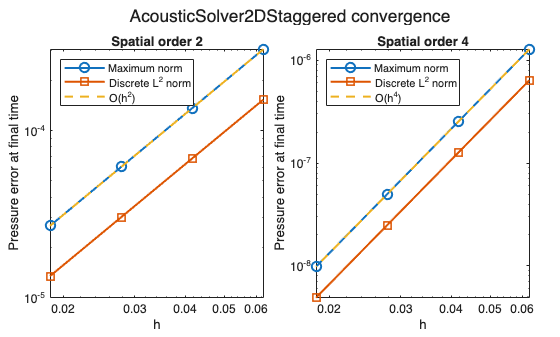

%% Plot convergence for both methods
figure;
layout = tiledlayout(1,2,TileSpacing="compact",Padding="compact");

for orderIndex = 1:numberOfOrders
    spatialOrder = spatialOrders(orderIndex);
    nexttile;
    loglog(h,errorInf(:,orderIndex),'-o', ...
        LineWidth=1.5,MarkerSize=7); hold on;
    loglog(h,errorL2(:,orderIndex),'-s', ...
        LineWidth=1.5,MarkerSize=7);

    referenceError = errorInf(1,orderIndex)* ...
        (h/h(1)).^spatialOrder;
    loglog(h,referenceError,'--',LineWidth=1.5);

    % grid on;
    xlabel('h');
    ylabel('Pressure error at final time');
    title(sprintf('Spatial order %d',spatialOrder));
    legend('Maximum norm','Discrete L^2 norm', ...
        sprintf('O(h^%d)',spatialOrder),Location='northwest');
end

title(layout,'AcousticSolver2DStaggered convergence');

%% Finest-grid summary
for orderIndex = 1:numberOfOrders
    fprintf(['Spatial order %d: finest-grid max rate = %.4f, ' ...
        'discrete-L2 rate = %.4f\n'], ...
        spatialOrders(orderIndex), ...
        observedOrderInf(end,orderIndex), ...
        observedOrderL2(end,orderIndex));
end

Spatial order 2: finest-grid max rate = 1.9996, discrete-L2 rate = 1.9996
Spatial order 4: finest-grid max rate = 3.9995, discrete-L2 rate = 3.9995
